## Matrix decomposition example in Proximal algorithms

Unofficial reimprementation of the example of matrix decomposition in *proximal algorithms.*

clear all;
rng(0);

% Data size
m = 20;  % number of rows
n = 50;  % number of colmuns

% Params
MAX_ITER = 300;
ABSTOL   = 1e-6;
RELTOL   = 1e-6;
N = 3;  % number of components
r = 2;  % rank
gamma_ratio = 0.15;

%  Data preparation
L = randn(m,r) * randn(r,n);
S = sprandn(m,n,0.05);
S(S ~= 0) = 20*binornd(1,0.5,nnz(S),1)-10;
V = 0.01*randn(m,n);

A = S + L + V;

% Set gamma
g2_max = norm(A(:),inf);
g3_max = norm(A);
g2 = gamma_ratio*g2_max;
g3 = gamma_ratio*g3_max;

% ADMM
X_1 = zeros(m,n);
X_2 = zeros(m,n);
X_3 = zeros(m,n);
z   = zeros(m,N*n);
U   = zeros(m,n);
lambda = 1;
rho = 1/lambda;

tic;
fprintf('\n%3s\t%10s\t%10s\t%10s\t%10s\t%10s\n', 'iter', ...
    'r norm', 'eps pri', 's norm', 'eps dual', 'objective');

iter	    r norm	   eps pri	    s norm	  eps dual	 objective



for k = 1:MAX_ITER

    B = avg(X_1, X_2, X_3) - A./N + U;

    % x-update
    X_1 = (1/(1+lambda))*(X_1 - B);
    X_2 = prox_l1(X_2 - B, lambda*g2);
    X_3 = prox_matrix(X_3 - B, lambda*g3, @prox_l1);

    % (for termination checks only)
    x = [X_1 X_2 X_3];
    zold = z;
    z = x + repmat(-avg(X_1, X_2, X_3) + A./N, 1, N);

    % u-update
    U = B;

    % diagnostics, reporting, termination checks
    h.objval(k)   = objective(X_1, g2, X_2, g3, X_3);
    h.r_norm(k)   = norm(x - z,'fro');
    h.s_norm(k)   = norm(-rho*(z - zold),'fro');
    h.eps_pri(k)  = sqrt(m*n*N)*ABSTOL + RELTOL*max(norm(x,'fro'), norm(-z,'fro'));
    h.eps_dual(k) = sqrt(m*n*N)*ABSTOL + RELTOL*sqrt(N)*norm(rho*U,'fro');

    if k == 1 || mod(k,10) == 0
        fprintf('%4d\t%10.4f\t%10.4f\t%10.4f\t%10.4f\t%10.2f\n', k, ...
            h.r_norm(k), h.eps_pri(k), h.s_norm(k), h.eps_dual(k), h.objval(k));
    end

    if h.r_norm(k) < h.eps_pri(k) && h.s_norm(k) < h.eps_dual(k)
         break;
    end

end

   1	   38.8512	    0.0001	   57.7264	    0.0001	    401.75
  10	   11.8740	    0.0001	    7.8561	    0.0001	   1939.32
  20	    3.9569	    0.0001	    2.5866	    0.0001	   1925.60
  30	    1.1275	    0.0001	    0.8149	    0.0001	   1849.33
  40	    0.5294	    0.0001	    0.2312	    0.0001	   1846.40
  50	    0.1854	    0.0001	    0.0896	    0.0001	   1843.46
  60	    0.0481	    0.0001	    0.0307	    0.0001	   1844.25
  70	    0.0150	    0.0001	    0.0098	    0.0001	   1843.55
  80	    0.0066	    0.0001	    0.0033	    0.0001	   1843.50
  90	    0.0031	    0.0001	    0.0012	    0.0001	   1843.63
 100	    0.0010	    0.0001	    0.0005	    0.0001	   1843.60
 110	    0.0002	    0.0001	    0.0002	    0.0001	   1843.61



h.admm_toc = toc;
h.admm_iter = k;
h.X1_admm = X_1;
h.X2_admm = X_2;
h.X3_admm = X_3;

fprintf('\nADMM (vs true):\n');


ADMM (vs true):


fprintf('|V| = %.2f;  |X_1| = %.2f\n', norm(V, 'fro'), norm(X_1,'fro'));

|V| = 0.31;  |X_1| = 23.16


fprintf('nnz(S) = %d; nnz(X_2) = %d\n', nnz(S), nnz(X_2));

nnz(S) = 50; nnz(X_2) = 50


fprintf('rank(L) = %d; rank(X_3) = %d\n', rank(L), rank(X_3));

rank(L) = 2; rank(X_3) = 2


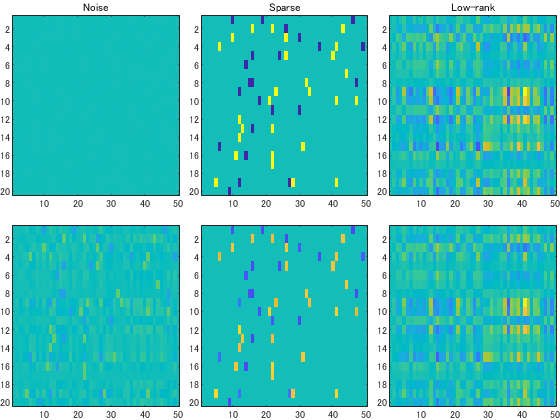

% Visualization
fig = figure;
t = tiledlayout(2, 3,'TileSpacing','compact','padding','none');
% Original
nexttile(1);
imagesc(V); caxis([-10, 10]); title('Noise')
nexttile(2);
imagesc(S); caxis([-10, 10]); title('Sparse')
nexttile(3);
imagesc(L); caxis([-10, 10]); title('Low-rank')
% Estimated
nexttile(4);
imagesc(X_1);  caxis([-10, 10]);
nexttile(5);
imagesc(X_2);  caxis([-10, 10]);
nexttile(6);
imagesc(X_3);  caxis([-10, 10]);

function p = objective(X_1, g2, X_2, g3, X_3)
    d = svd(X_3,'econ');
    p = 0.5*norm(X_1,'fro')^2 + g2*norm(X_2(:),1) + g3*norm(d,1);
end

function x = avg(varargin)
    N = length(varargin);
    x = 0;
    for k = 1:N
        x = x + varargin{k};
    end
    x = x/N;
end

function x = prox_l1(v, lambda)
% PROX_L1    The proximal operator of the l1 norm.
%
%   prox_l1(v,lambda) is the proximal operator of the l1 norm
%   with parameter lambda.
    x = max(0, v - lambda) - max(0, -v - lambda);
end

function x = prox_matrix(v, lambda, prox_f)
% PROX_MATRIX    The proximal operator of a matrix function.
%
%   Suppose F is a orthogonally invariant matrix function such that
%   F(X) = f(s(X)), where s is the singular value map and f is some
%   absolutely symmetric function. Then
%
%     X = prox_matrix(V,lambda,prox_f)
%
%   evaluates the proximal operator of F via the proximal operator
%   of f. Here, it must be possible to evaluate prox_f as prox_f(v,lambda).
%
%   For example,
%
%     prox_matrix(V,lambda,prox_l1)
%
%   evaluates the proximal operator of the nuclear norm at V
%   (i.e., the singular value thresholding operator).

    [U,S,V] = svd(v,'econ');
    x = U*diag(prox_f(diag(S), lambda))*V';
end

Reference: N. Parikh and S. Boyd, "Proximal Algorithms," Foundations and Trends in Optimization, 1(3):123-231, 2014.

Official Code: [https://web.stanford.edu/~boyd/papers/prox_algs/matrix_decomp.html](https://web.stanford.edu/~boyd/papers/prox_algs/matrix_decomp.html)

Proximal operators are available here: [https://github.com/cvxgrp/proximal](https://github.com/cvxgrp/proximal)